%calculating the mean first passage time analytically/numerically 
%to investigate effect of branch migration domain length on RNA/DNA toehold
%exchange kinetics including spontaneous incumbent dissociation

%b = 20 %define branch migration domain length

b = 20

g2 = 2 %define incumbent toehold length

g2 = 2

g = 3 %define invader toehold length

g = 3


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -0.3*R*temp

dGrd = -0.1777

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,30)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 30)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 30)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through branch migration domain lengths
for b = 10:40
    bg2 = b + g2 %define branch migration domain + incumbent toehold length 

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp * exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates
    Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
    %define spontaneous incumbent dissociation rates
    Koff = [repmat(0, [1, g2+1])]; 
    for n = g2+1:bg2-1
        Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
    end
    Koff = horzcat(Koff, [repmat(0, [1, g+1])])
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    first_pass_time (b-9) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time
    k_eff (b-9) = 1/(first_pass_time (b-9)*(5*10^-8)); %calculate effective rate constant
    prob_unbound(b-9) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate prob of being in unbound state
end

bg2 = 12

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 13

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 14

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 15

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 16

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 17

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 18

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 19

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 20

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 21

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 22

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 23

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 24

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 25

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 26

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 27

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219    0.3219


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 28

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219    0.3219


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 29

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0009


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.3219


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 30

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0


bg2 = 31

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0


bg2 = 32

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0


bg2 = 33

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0


bg2 = 34

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0         0


bg2 = 35

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415  249.2469         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0         0


bg2 = 36

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415  249.2469  249.2509         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0         0


bg2 = 37

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415  249.2469  249.2509  249.2539         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0         0


bg2 = 38

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415  249.2469  249.2509  249.2539  249.2562         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0         0


bg2 = 39

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415  249.2469  249.2509  249.2539  249.2562  249.2579         0         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0         0


bg2 = 40

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415  249.2469  249.2509  249.2539  249.2562  249.2579  249.2592         0


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000         0


bg2 = 41

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415  249.2469  249.2509  249.2539  249.2562  249.2579  249.2592  249.2602


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


bg2 = 42

k_AB1 = 0.2005

k_B1A = 3.2187e+06

ans = 4.3448e+06

k_BC1ji = 3.2187e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.4453e+04

k_DC = 668.1379

k_FE = 0

k_FF = 1

Kf =     0.0000    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Kb =          0    5.4000    0.0001    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024    0.0024


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =   234.2652  238.1515  241.0306  243.1635  244.7436  245.9142  246.7815  247.4240  247.9000  248.2527  248.5139  248.7075  248.8510  248.9573  249.0361  249.0945  249.1378  249.1699  249.1937  249.2113  249.2245  249.2342  249.2415  249.2469  249.2509  249.2539  249.2562  249.2579  249.2592  249.2602


prob_unbound =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


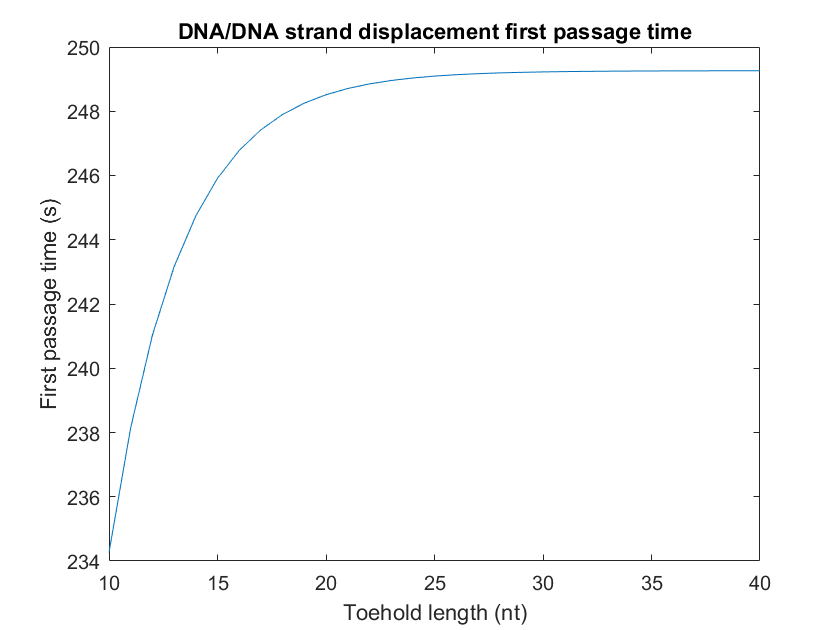

plot(10:40, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

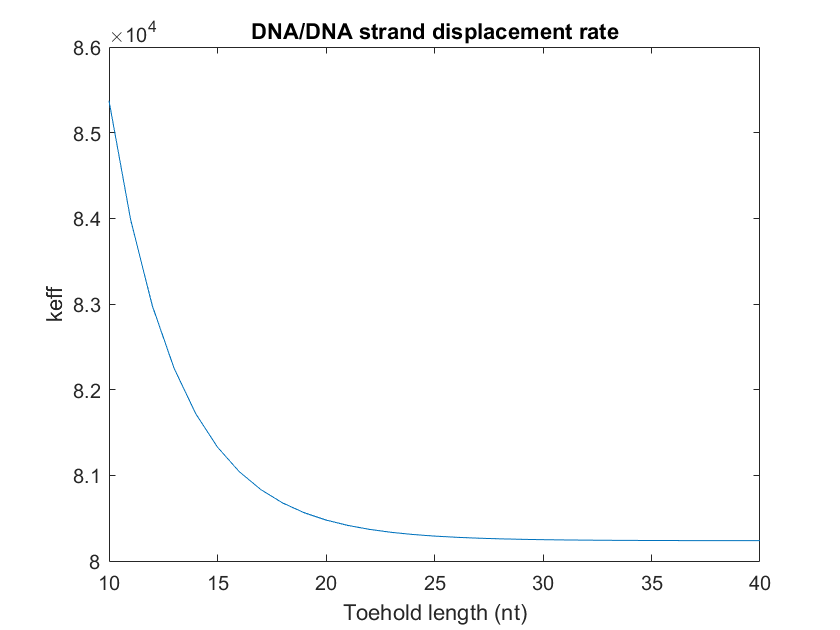


plot(10:40, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

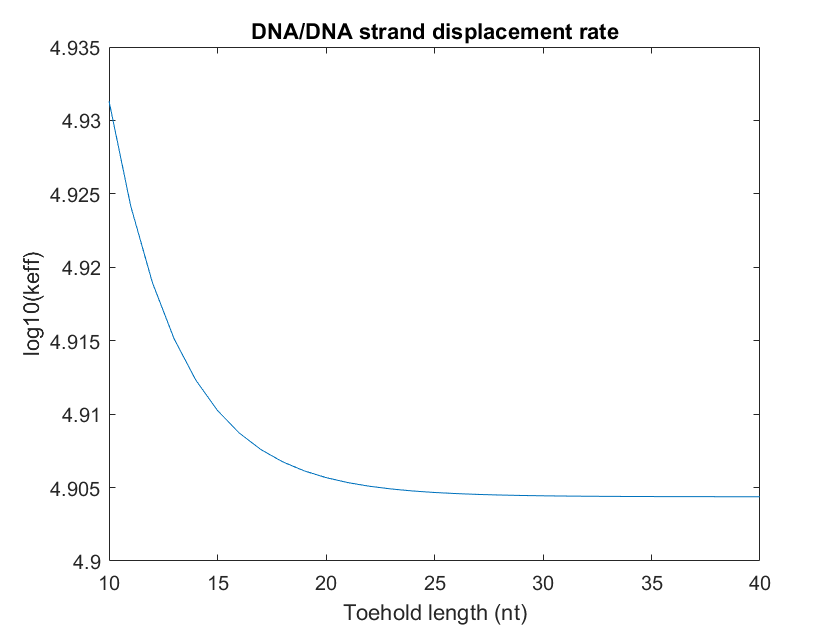


plot(10:40, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  